clc; % czysci command window
clear; %czysci zmienne
close; %zamyka wszystkie okna

## Geometria i geometria odwrotna

Wykres wydłużenia siłownika w funkcji kąta wychylenia steru

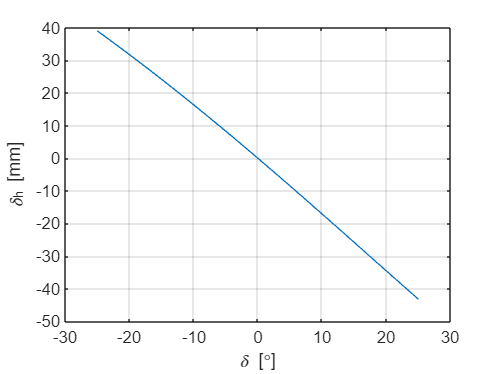

y_max = 100;
L = 180;
R=100;
Y=180;
alpha=asin(R/(2*L));
alpha_prim=pi/2 - alpha;

delta=-25:0.1:25;

delta_h = -(Y-sqrt(L^2+R^2-2*L*R*cos(alpha_prim-delta*pi/180)));

figure;
plot(delta,delta_h);
grid on
xlabel('\delta [\circ]');
ylabel('\delta_h [mm]');
grid on
hold on

## Dynamika układu

Zależność siły wzdłużnej w siłowniku od kąta wychylenia steru i momentu aerodynamicznego

v_dzwieku = 340.3;
Ma= 0.3;
v_lotu = v_dzwieku*Ma;
c = 2.37;
rho = 1.2255;
b = 5;
wsp1 = 0.5*rho*v_lotu^2 * c^2 * b;

delta_dyn = [-25, 20, -10, 0, 10, 20, 25];
cm_h = [-0.033139, -0.027379, -0.017291, -0.000038, 0.017291, 0.027379, 0.033139];
M_h = wsp1*cm_h;

    delta_h_dyn = -(Y-sqrt(L^2+R^2-2*L*R.*cos(alpha_prim-delta_dyn*pi/180)));
    beta = acos((R^2 +delta_h_dyn.*(delta_h_dyn+2*L))./(2*R*(L+delta_h_dyn))) - pi/2;
    R_B = M_h./(R*cos(beta))

R_B =   -73.1841  -49.1495  -34.0256   -0.0709   31.2667   49.1495   59.9813


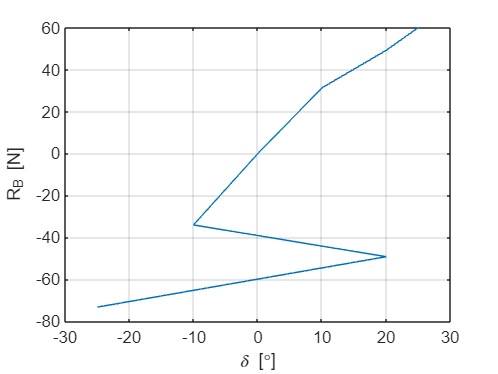




figure;
plot(delta_dyn,R_B);
grid on
xlabel('\delta [\circ]');
ylabel('R_B [N]');
grid on
hold on